[Signal Enhancement Using LMS and NLMS Algorithms - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/dsp/ug/enhance-a-signal-using-lms-and-normalized-lms-algorithms.html)

## Model

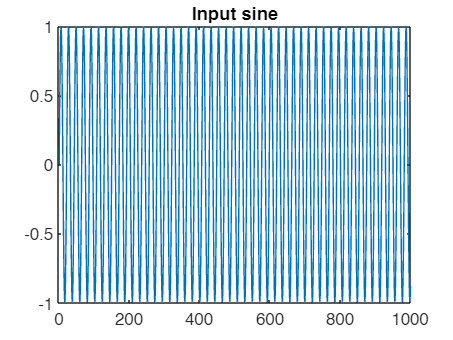

signed = 1;
word_len = 32;
frac_len = 20;
T = numerictype(signed, word_len, frac_len);
rng(0);

% Signal generation
sine = dsp.SineWave('Frequency',375,'SampleRate',8000,'SamplesPerFrame',1000);
s = sine();
plot(s)
title("Input sine")

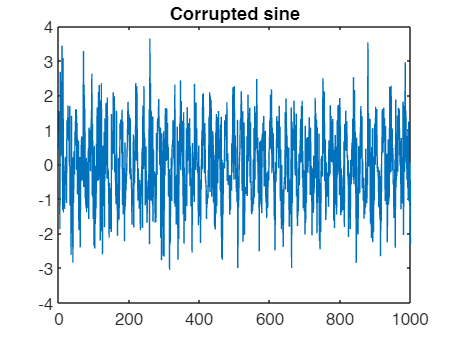


% Noise generation
v = 0.8*randn(sine.SamplesPerFrame,1); % Random noise part.
ar = [1,1/2]; % Autoregression coefficients.
ARfilt = dsp.IIRFilter('Numerator',1,'Denominator',ar);
v1 = ARfilt(v);

% Corrupted input
x = s + v1;
plot(x)
title("Corrupted sine")

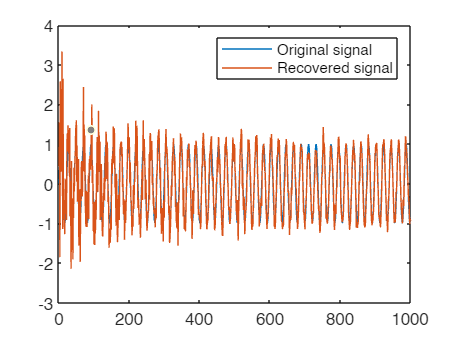


% Correlated noise input
ma = [1, -0.8, 0.4, -0.2];
MAfilt = dsp.FIRFilter('Numerator',ma);
v2 = MAfilt(v);

L = 7;
lms = dsp.LMSFilter(L,'Method','LMS');
[mumaxlms,mumaxmselms] = maxstep(lms,x);
lms.StepSize  = mumaxmselms/30;
[y,elms,wlms] = lms(fi(v2,T),fi(x,T));
plot([s elms])
legend('Original signal', 'Recovered signal')

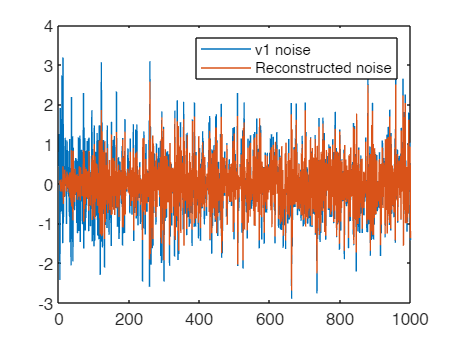


plot([v1 y])
legend('v1 noise', 'Reconstructed noise')

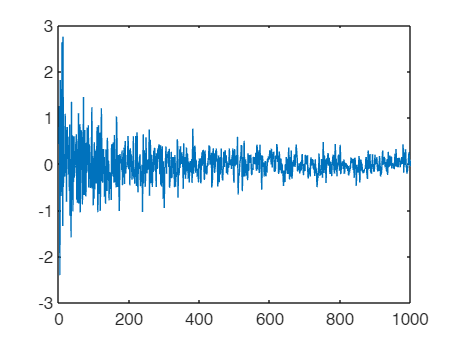


plot(v1-y)

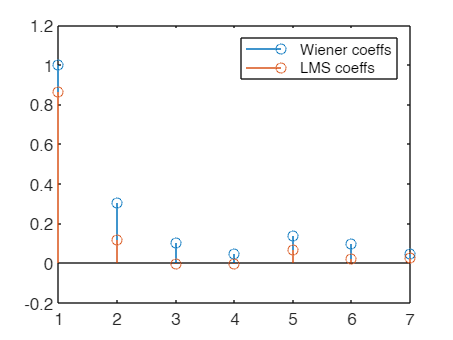


bw = firwiener(L-1,v2,x); % Optimal FIR Wiener filter
MAfilt = dsp.FIRFilter('Numerator',bw);

stem([bw.' wlms])
legend('Wiener coeffs', 'LMS coeffs')

## Sim inputs

save_dec_txt(x, T, "data/desired.txt");
save_dec_txt(v2, T, "data/input.txt");
save_dec_txt(lms.StepSize, T, "data/step_size.txt");

## Simulation

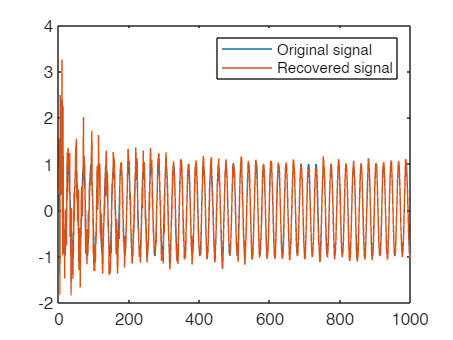

error = load_dec_txt("data/error.txt", T);
plot([s error])
legend('Original signal', 'Recovered signal')

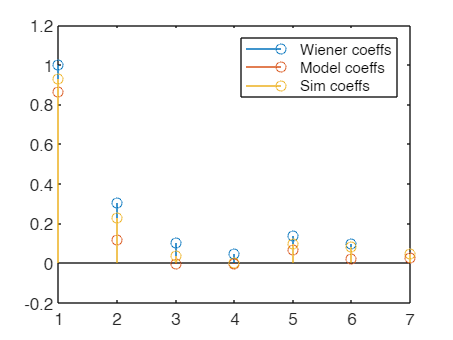


weights = load_dec_txt("data/weights.txt", T);
stem([bw.' wlms weights]);
legend('Wiener coeffs', 'Model coeffs', 'Sim coeffs')